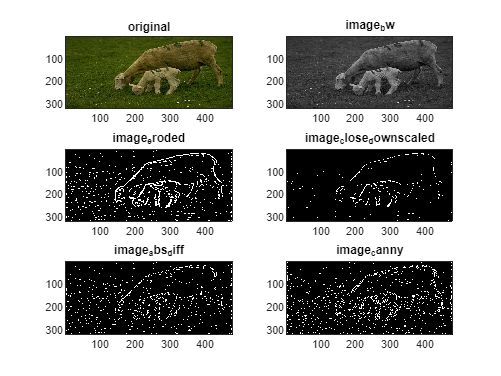

I = imread('Images/im11.jpg');
I = im2double(I);

image_bw = rgb2gray(I);

dog = fspecial('gaussian',60,1.25)-fspecial('gaussian',60,3.0);
image_dog = conv2(image_bw,dog,'same');

image_dog = imbinarize(image_dog);
image_bw_upscaled = imresize(image_dog, 2, "bilinear");

kernel_morphology = [1 1 1; 1 1 1; 1 1 1];
image_close = imerode(image_bw_upscaled, kernel_morphology);

image_close_downscaled = imresize(image_close, 0.5, "bilinear");

image_abs_diff = imabsdiff(image_dog, image_close_downscaled);


image_canny = edge(image_abs_diff,'canny', 0.33, 0.36);



subplot(3,2,1); imagesc(I); colormap('default'); title('original')
subplot(3,2,2); imagesc(image_bw); colormap('gray'); title('image_bw')
subplot(3,2,3); imagesc(image_dog); colormap('gray'); title('image_eroded')
subplot(3,2,4); imagesc(image_close_downscaled); colormap('gray'); title('image_close_downscaled')
subplot(3,2,5); imagesc(image_abs_diff); colormap('gray'); title('image_abs_diff')
subplot(3,2,6); imagesc(image_canny); colormap('gray'); title('image_canny')